%base parameters 
bandwidth = 4000;
audio_min= 300;
snr = 20;

%carrier frequency initiaisation 
frec_carrier1 = bandwidth*3;%12000
frec_carrier2 = bandwidth*4;%16000
frec_carrier3 = bandwidth*5;
Fs = frec_carrier3*2+5000;  %sampling frequency 

freq_cutoff= 2500; %sound 50Hz to 2800Hz

%filter definition 
[B,A] = butter(4,freq_cutoff/(Fs/2));
pass_band= @(S) filter(B,A,S);
[C1,D1] = butter(2,[bandwidth*2+audio_min bandwidth*3-audio_min]/(Fs/2));
filter_band3 = @(S) filter(C1,D1,S);
[C2,D2] = butter(2,[bandwidth*3+audio_min bandwidth*4-audio_min]/(Fs/2));
filter_band4 = @(S) filter(C2,D2,S);



%audio read 
Fs = 44100;%default is 8192 
noc= 1;
nob=16;%8,16,24
recObj = audiorecorder(Fs,nob,noc);  
disp("Recording Voice 1 for 3- seconds ");

Recording Voice 1 for 3- seconds 


recordblocking(recObj,3);
s1= getaudiodata(recObj);
longituds1 = length(s1);
disp("Recording Voice 2 for 3- seconds ");

Recording Voice 2 for 3- seconds 


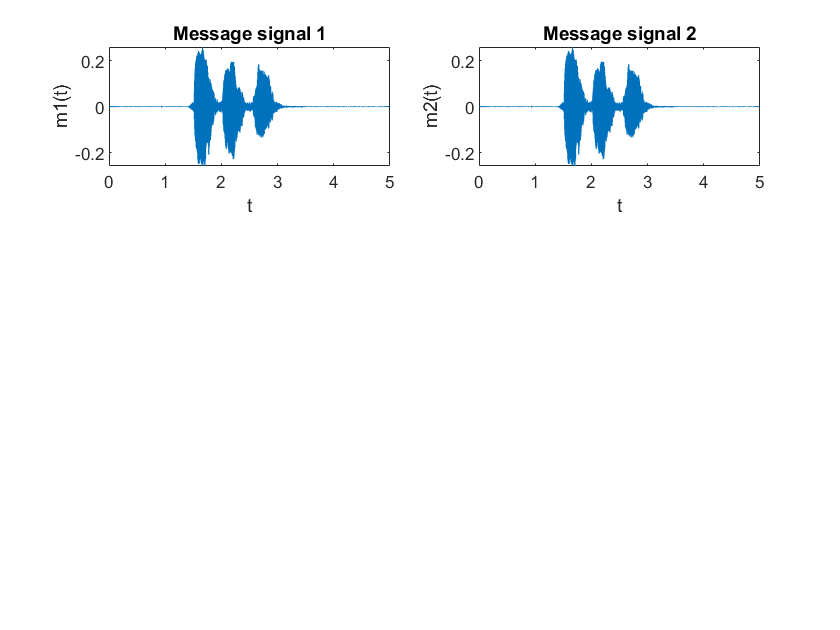

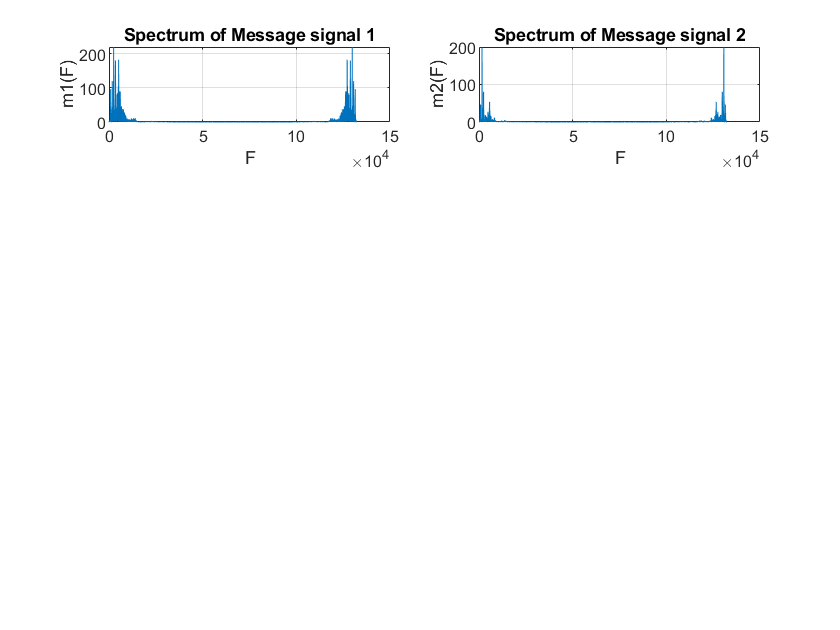

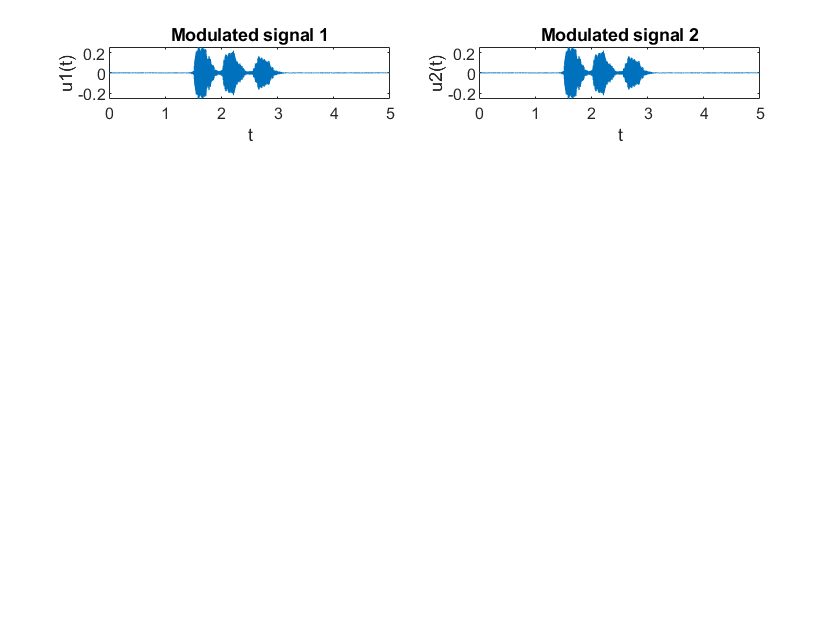

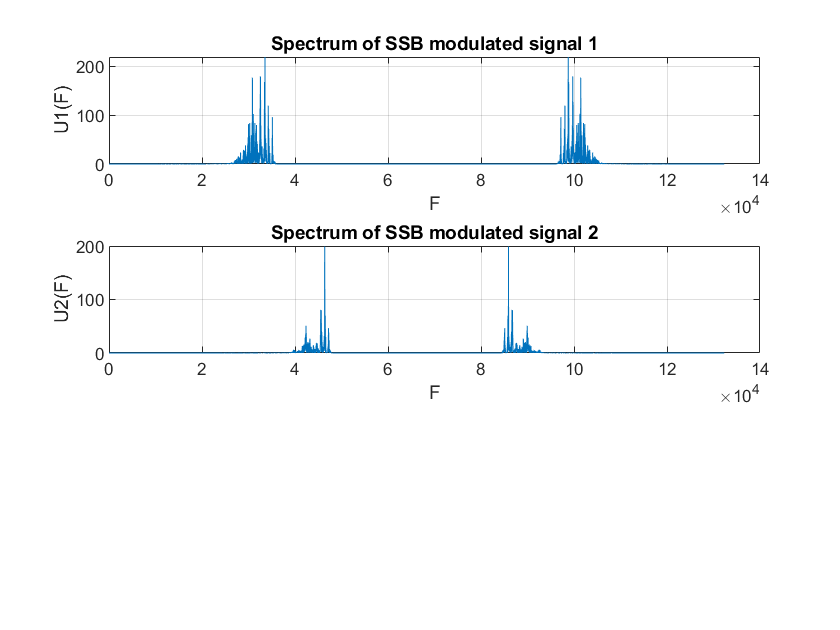

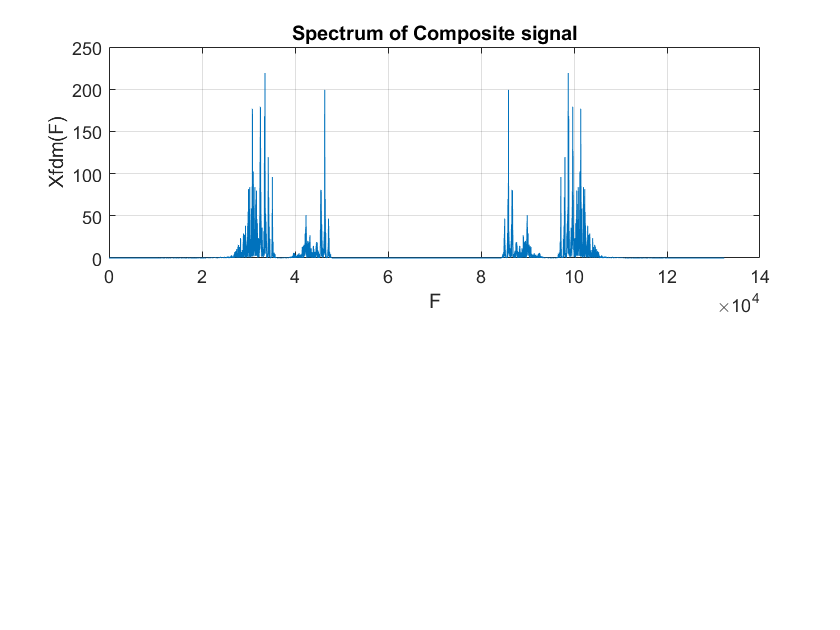

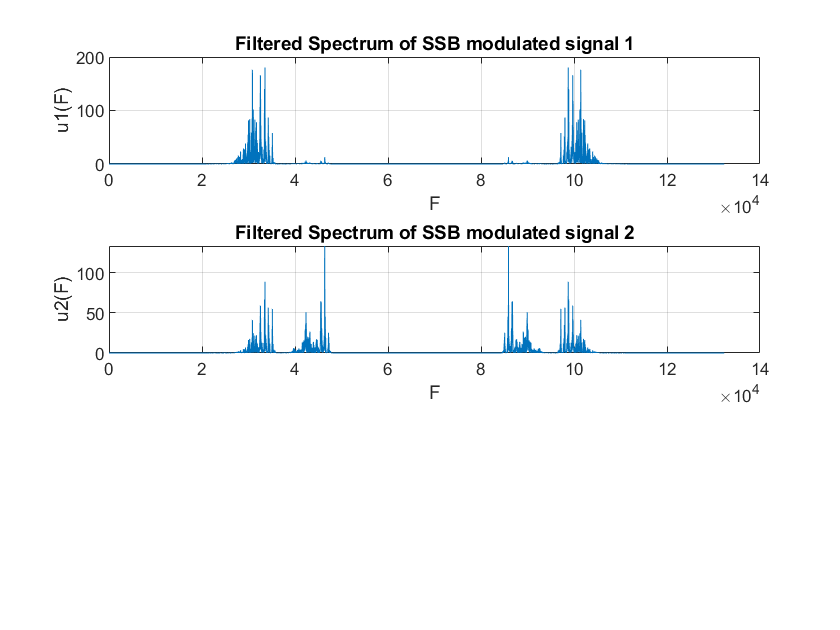

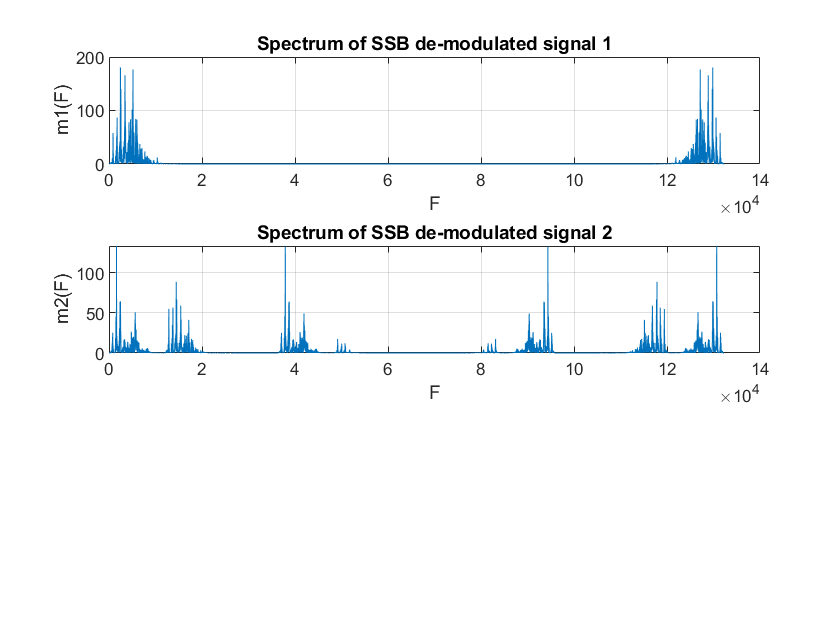

recordblocking(recObj,3);
s2= getaudiodata(recObj);

longituds2 = length(s2);

%truncation_block
longitud_minima = min([longituds1 longituds2]);
t = linspace(0,5, longitud_minima);
s1 = s1(1:longitud_minima);
s2 = s2(1:longitud_minima);
figure
subplot(3,2,1)
plot(t,s1);
title('Message signal 1');
xlabel('t');
ylabel('m1(t)');
subplot(3,2,2)
plot(t,s1);
title('Message signal 2');
xlabel('t');
ylabel('m2(t)');



%plotting of fft 

esps1=abs(fft(s1));
figure
subplot(4,2,1);
plot(esps1);grid on;zoom,title('Spectrum of Message signal 1');
xlabel('F');
ylabel('m1(F)');
esps2=abs(fft(s2));
subplot(4,2,2),plot(esps2),grid on;zoom,title('Spectrum of Message signal 2');
xlabel('F');
ylabel('m2(F)');


%low pass filter 
s1 = pass_band(s1); %reffer 
s2 = pass_band(s2);



%ssb modulation 
s1mod = ssbmod(s1,frec_carrier1,Fs);%se modula
s2mod = ssbmod(s2,frec_carrier2,Fs);%se modula

%ploting ssb modultation
figure
subplot(5,2,1);
plot(t,s1mod);
title('Modulated signal 1');
xlabel('t');
ylabel('u1(t)');
subplot(5,2,2);
plot(t,s1mod);
title('Modulated signal 2');
xlabel('t');
ylabel('u2(t)');
figure
esps1=abs(fft(s1mod));
subplot(3,1,1),plot(esps1),grid on;zoom,title('Spectrum of SSB modulated signal 1');
xlabel('F');
ylabel('U1(F)');

esps2=abs(fft(s2mod));
subplot(3,1,2),plot(esps2),grid on;zoom,title('Spectrum of SSB modulated signal 2');
xlabel('F');
ylabel('U2(F)');

%fdm

fs1 = s1mod;
fs2 = s2mod;
senial_completa = fs1+fs2;
figure
esps1=abs(fft(senial_completa));
subplot(2,1,1),plot(esps1),grid on;zoom,title('Spectrum of Composite signal');
xlabel('F');
ylabel('Xfdm(F)');


%retrieval 
%demuxs1=filter(filtro_banda1,senial_completa);%se filtra
demuxs1 = filter_band3(senial_completa);
%demuxs2=filter(filtro_banda2,senial_completa);%se filtra
demuxs2 = filter_band4(senial_completa);

figure
esps1=abs(fft(demuxs1));
subplot(3,1,1),plot(esps1),grid on;zoom,title('Filtered Spectrum of SSB modulated signal 1');
xlabel('F');
ylabel('u1(F)');
esps2=abs(fft(demuxs2));
subplot(3,1,2),plot(esps2),grid on;zoom,title('Filtered Spectrum of SSB modulated signal 2');
xlabel('F');
ylabel('u2(F)');


%ssb demodulation 

demods1 = ssbdemod(demuxs1, frec_carrier1,Fs);
demods2 = ssbdemod(demuxs2, frec_carrier2,Fs);

figure
esps1=abs(fft(demods1));
subplot(3,1,1),plot(esps1),grid on;zoom,title('Spectrum of SSB de-modulated signal 1');
xlabel('F');
ylabel('m1(F)');
esps2=abs(fft(demods2));
subplot(3,1,2),plot(esps2),grid on;zoom,title('Spectrum of SSB de-modulated signal 2');
xlabel('F');
ylabel('m2(F)');

%further filtering 
demods1 = pass_band(demods1);
demods2 = pass_band(demods2);
 
%final audio replay 
k=5;

while k==5
choice = input("Whose voice you want to extract");
if choice==1
player4 = audioplayer(demods1,44100);
playblocking(player4);
end

if choice==2
player5 = audioplayer(demods2,44100);
playblocking(player5);
end
k = input("do you want to cotinue? (y=5/n=6)");
end